# Simulação do Motor usando uma estimativa de função de transferencia

## Mostrando dados coletados

data_est = vetorrpm

data_est =

Time domain data set with 2040 samples.
Sample time: 0.001 seconds              
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


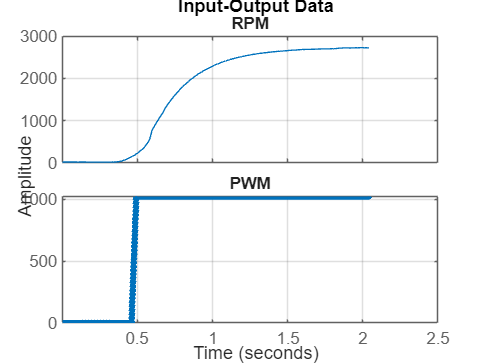

opt = compareOptions;
data_est.InputName = 'PWM';
data_est.OutputName = 'RPM';
data_est.TimeUnit = 'seconds';
plot(data_est);
set(findall(gca,'Type','Line'),'LineWidth',4);
grid on

val_data = vetorrpm2

val_data =

Time domain data set with 7620 samples.
Sample time: 0.001 seconds              
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


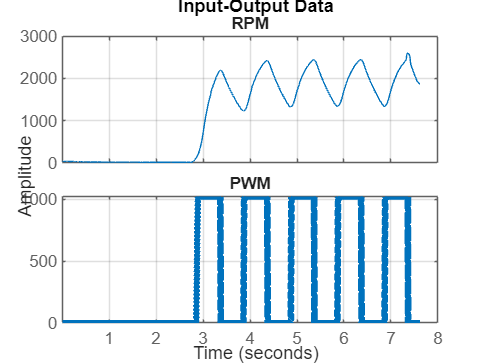


val_data.InputName = 'PWM';
val_data.OutputName = 'RPM';
val_data.TimeUnit = 'seconds';
plot(val_data);
set(findall(gca,'Type','Line'),'LineWidth',4);
grid on

val2_data = vetorrpm3

val2_data =

Time domain data set with 26932 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


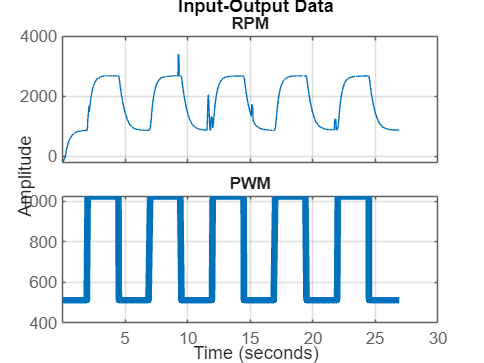


val2_data.InputName = 'PWM';
val2_data.OutputName = 'RPM';
val2_data.TimeUnit = 'seconds';
plot(val2_data);
set(findall(gca,'Type','Line'),'LineWidth',4);
grid on

val3_data = vetorrpm4

val3_data =

Time domain data set with 14017 samples.
Sample time: 0.001 seconds               
                                         
Outputs      Unit (if specified)         
   y1                                    
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


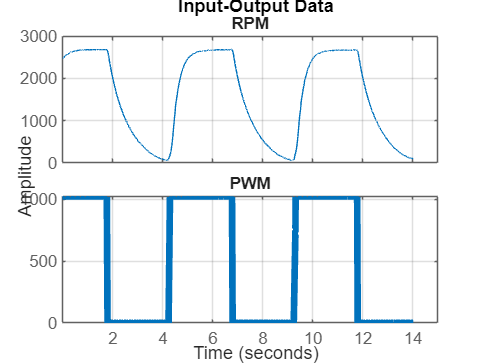


val3_data.InputName = 'PWM';
val3_data.OutputName = 'RPM';
val3_data.TimeUnit = 'seconds';
plot(val3_data);
set(findall(gca,'Type','Line'),'LineWidth',4);
grid on

decline = queda

decline =

Time domain data set with 2942 samples.
Sample time: 0.001 seconds              
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


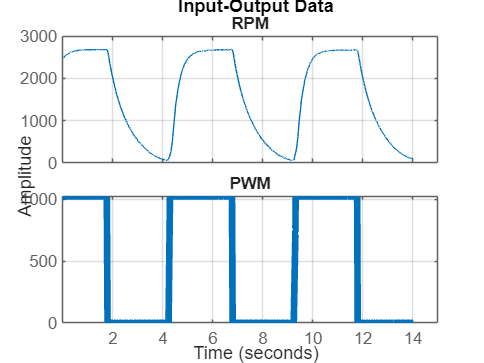

val3_data.InputName = 'PWM';
val3_data.OutputName = 'RPM';
val3_data.TimeUnit = 'seconds';
plot(val3_data);
set(findall(gca,'Type','Line'),'LineWidth',4);
grid on

decline.InputName = 'PWM';
decline.OutputName = 'RPM';
decline.TimeUnit = 'seconds';
plot(val3_data);
set(findall(gca,'Type','Line'),'LineWidth',4);
grid on

## Estimando a FT por espaço de estados

Gest=tfest(data_est,1,0,NaN)

Gest =
  From input "PWM" to output "RPM":
                   9.613
  exp(-0.029*s) * --------
                  s + 3.59
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "data_est".
Fit to estimation data: 96.64%                       
FPE: 1401, MSE: 1396                                 
 
Model Properties


## Testando a FT nos dados

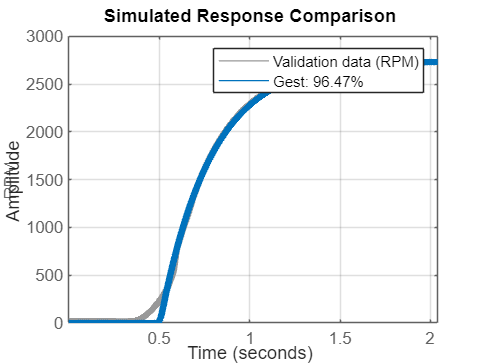

opt.InitialCondition='z'; 
compare(data_est,Gest,opt);
set(findall(gca,'Type','Line'),'LineWidth',4);
grid on

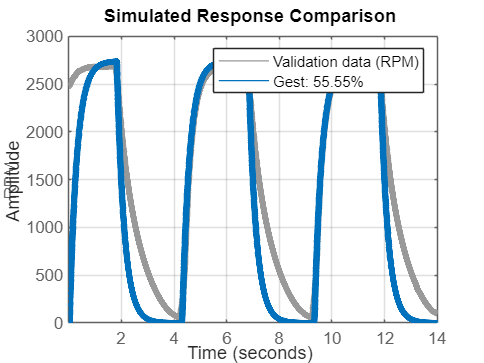


opt.InitialCondition='z';
compare(val3_data,Gest,opt);
set(findall(gca,'Type','Line'),'LineWidth',4);
grid on

## Residuais da FT

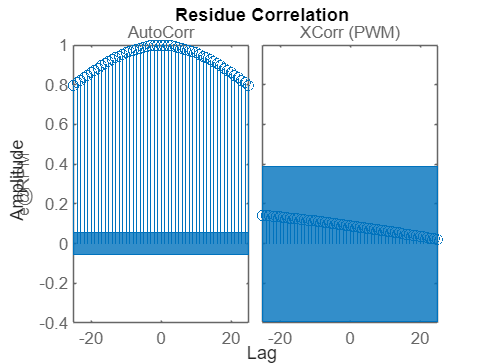

resid(Gest,data_est);

sysFinal=tf(Gest)

sysFinal =
 
  From input "PWM" to output "RPM":
                   9.613
  exp(-0.029*s) * --------
                  s + 3.59
 
Continuous-time transfer function.
Model Properties
